# 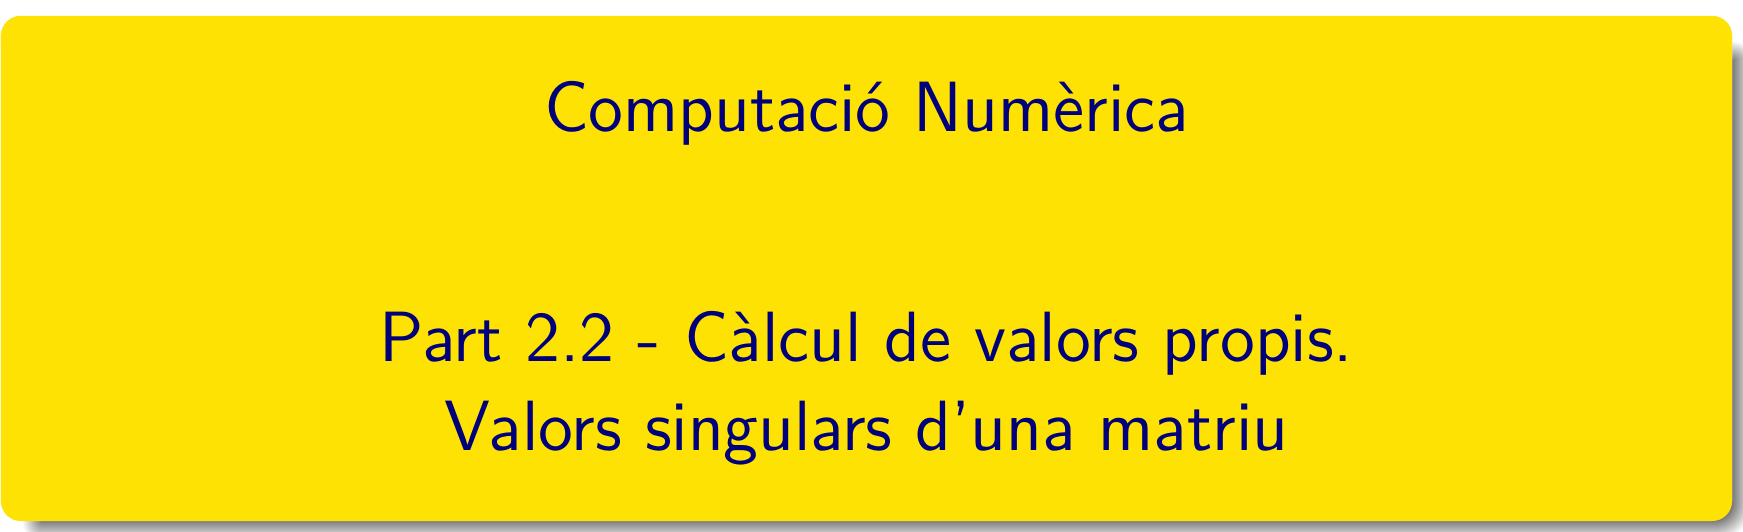

======================================================================================================

# TEMA 2. ÀLGEBRA LINEAL NUMÈRICA

## 2.2 Valors i vectors propis d'una matriu. Mètode QR

### Part I. Matrius Hessenberg

Una matriu quadrada d'ordre n, $A$  es **Hessenberg superior si** ${\displaystyle a_{i,j}=0}$ per a tot ${\displaystyle i,j}$ amb ${\displaystyle i>j+1}$.

Una matriu quadrada d'ordre n, $A$  es **Hessenberg inferior si** ${\displaystyle a_{i,j}=0}$ per a tot ${\displaystyle i,j}$ amb  ${\displaystyle j>i+1}$.

Una tècnica per reduir a forma Hessenberg es via les matrius ortogonals de Householder.  En un pas, es transforma una columna

en n-2 pasos, la matriu és 

El nombre d'operacions és cost $\approx 10\,n^3/3$flops. Si la matriu $A$ és simètrica, s'obté una tridiagonal amb un cost reduït a cost $\approx 4\,n^3/3$

Reduccions de Householder. 

% rng('default')
% A = randn(6,3)               % matriu qualsevol
% [v1,beta1] = gallery('house',A(:,1));
% P1 = eye(6) - beta1*(v1*v1');
% A1 = P1*A                    % Primera columna
% [v2,beta2] = gallery('house',A1(2:end,2));
% P2 = eye(5) - beta2*(v2*v2');
% PP = eye(6); PP(2:end,2:end) = P2 
% A2 = PP*A1                   % Segona columna
% [v3,beta3] = gallery('house',A2(3:end,3));
% P3 = eye(4) - beta3*(v3*v3')
% PP = eye(6); PP(3:end,3:end) = P3 
% A3 = PP*A2                   % Tercera columna

Obteniu la forma Hessenberg per a la matriu següent:


$$\left(  \begin{array}{rrrr} 0 &  12 &  16 & -15\\
12 & 388 & 309 & 185\\
16 & 309 & 312 & 80\\
-15 & 185 & 80  & -600
\end{array} \right)$$


clearvars;
A = [0 12 16 -15; 12 388 309 185; 16 309 312 80; -15 185 80 -600], H = hess(A)
A = rand(7), H = hess(A)

### Part II. Mètode QR.

[The QR Algorithm Computes Eigenvalues and Singular Values](https://blogs.mathworks.com/cleve/2019/08/05/the-qr-algorithm-computes-eigenvalues-and-singular-values/)

% A = fliplr(rosser)   %, imagesc(A), axis square, colorbar
% D = eigsvdgui(A, 'eig');
% format shortG, vaps = diag(D)
% B = (A+A')/2   %, imagesc(A), axis square, colorbar
% D = eigsvdgui(A, 'symm'), vaps = diag(D)
% I = eye(8,8); A = [A(1:4,:); I(1,:); A(5:8,:); I(2,:)]
% D = eigsvdgui(A, 'svd'); singularvalues = diag(D)

### Jocs de proves

#### Exemple 1. Valors propis  de matriu no simètrica


$$\left( \begin{array}{rrrr} 1 & 2 &  1 & 2\\
2 & 2 & -1 & 1\\
1 & -1 & 1 & 1\\
1 & 1 & 1 & 1
\end{array}\right)$$


A = [1 2 1 2; 2 2 -1 1; 1 -1 1 1; 1 1 1 1]
[D,steps] = myqrmethod(A)
U = schur(A)

#### Exemple 2. Valors propis de matriu simètrica


$$\left(  \begin{array}{rrrr} 0 &  12 &  16 & -15\\
12 & 388 & 309 & 185\\
16 & 309 & 312 & 80\\
-15 & 185 & 80  & -600
\end{array} \right)$$


A= [0 12 16 -15; 12 388 309 185; 16 309 312 80; -15 185 80 -600]
[D,steps] = myqrmethod(A)
U = schur(A)

#### Exemple 3. Mètode QR


$$\left(  \begin{array}{rrrr} 1 & -4 & -1 & -4\\
2 & 0 & 5 & -4\\
-1 & 1 & -2 & 3\\
-1 & 4 & -1 & 6
\end{array} \right)$$


A= [1 -4 -1 -4; 2 0 5 -4; -1 1 -2 3; -1 4 -1 6]
[D,steps] = myqrmethod(A)
U = schur(A)

#### Exemple 4. Valors propis complexos

A = gallery('dramadah',6);
[D,steps] = myqrmethod(A)
U = schur(A)

function [H,steps] = myqrmethod(A)
% Computes all the eigenvalues of a matrix using the QR method.
% Input: A -- square matrix
% Outputs: E -- vector of eigenvalues
% steps -- the number of iterations it took
[m n] = size(A);

A =      1     2     1     2
     2     2    -1     1
     1    -1     1     1
     1     1     1     1


if m ~= n

change = 1.9293e-16

H =     4.4495   -0.1151   -0.0247    0.7493
    0.0000    2.3028    0.0962   -0.3249
         0   -0.0000   -1.3028    0.5566
         0         0   -0.0000   -0.4495


D =     4.4495   -0.1151   -0.0247    0.7493
    0.0000    2.3028    0.0962   -0.3249
         0   -0.0000   -1.3028    0.5566
         0         0   -0.0000   -0.4495


steps = 71

    warning('The input matrix is not square.')

U =     4.4495   -0.0216   -0.7317   -0.1988
         0   -1.3028   -0.5508   -0.1588
         0         0   -0.4495   -0.3099
         0         0         0    2.3028


return
end
% Set up initial estimate
H = hess(A);

A =      0    12    16   -15
    12   388   309   185
    16   309   312    80
   -15   185    80  -600


E = diag(H);

change = 1.5032e-07

H =   690.3367   -0.0000   -0.0000    0.0000
   -0.0000 -634.6322   -0.0000    0.0000
         0   -0.0000   45.0188    0.0000
         0         0         0   -0.7233


D =   690.3367   -0.0000   -0.0000    0.0000
   -0.0000 -634.6322   -0.0000    0.0000
         0   -0.0000   45.0188    0.0000
         0         0         0   -0.7233


steps = 250

change = 1;

U =  -634.6322         0         0         0
         0   -0.7233         0         0
         0         0   45.0188         0
         0         0         0  690.3367


steps = 0;
% loop while estimate changes
while (change > eps && steps < 250)
    Eold = E;

A =      1    -4    -1    -4
     2     0     5    -4
    -1     1    -2     3
    -1     4    -1     6


    % apply QR method

change = 4.2601e-05

H =     2.0000    9.0322   -4.3143   -3.2814
   -0.0000    1.0080    2.6974   -4.7108
         0   -0.0000    1.0000   -0.7556
         0         0    0.0000    0.9920


D =     2.0000    9.0322   -4.3143   -3.2814
   -0.0000    1.0080    2.6974   -4.7108
         0   -0.0000    1.0000   -0.7556
         0         0    0.0000    0.9920


steps = 250

    [Q R] = qr(H);

U =     2.0000    9.0451   -4.3215   -3.2360
         0    1.0000    2.6476   -4.7367
         0         0    1.0000   -0.7698
         0         0    0.0000    1.0000


    H = R*Q;
    % test change
    change = norm(tril(H,-1));
    steps = steps +1;

change = 1.0547

H =     3.1668    0.1234   -0.1341    0.4859    0.1582   -0.0234
   -0.0000    1.5764   -0.8157    0.0668    0.2833    0.3565
         0    0.1302    1.2152    0.4958   -0.6338    0.7605
         0         0    0.0000    0.2400    0.8839    0.6054
         0         0         0   -1.0547   -0.0296    0.4976
         0         0         0         0   -0.0000   -0.1688


D =     3.1668    0.1234   -0.1341    0.4859    0.1582   -0.0234
   -0.0000    1.5764   -0.8157    0.0668    0.2833    0.3565
         0    0.1302    1.2152    0.4958   -0.6338    0.7605
         0         0    0.0000    0.2400    0.8839    0.6054
         0         0         0   -1.0547   -0.0296    0.4976
         0         0         0         0   -0.0000   -0.1688


steps = 250

end

U =     3.1668    0.3579    0.3016   -0.1851    0.1965    0.0542
         0    0.1052   -0.8168    0.7739   -0.2061   -0.1557
         0    1.1192    0.1052   -0.1635    0.1465   -0.4046
         0         0         0   -0.1688   -1.0312   -0.3590
         0         0         0         0    1.3958   -0.8559
         0         0         0         0    0.0860    1.3958


change,H
end
%------------------------------------------------------------------